Set some initial things like some realistic echo times and transverse relaxation times.  Then make a general simulation of the data based on the settings.

clear;close all;clc
te1=0.0088;
te2=0.026;
te3=0.050;
te4=0.068;
te5=0.0765;
Spin_echo=0.088;
% echo_times = [te1 te2 te3 te4 te5 Spin_echo];

% Define an asymetric echo 10% higher longer than SE/2
% It does better with 2 to be nearly exactly the same as the Linear algebra solution. What percentage is best.
frac =0.8;
a = Spin_echo/2+(frac*(Spin_echo/2));

num_asym_p_spinecho = 10;            % how many echos to simulate
num_echos = 2+num_asym_p_spinecho;  % Account for all echos
echo_times = [te1 te2 linspace(a,Spin_echo,num_asym_p_spinecho)];

N = 1000;
S01 = 2000;
delta = 1;
S02 = S01/delta;
R2s = 30;
R2s = randn(1)+(0.05*R2s)+R2s;
R2 = 16;
R2 = randn(1)+(0.05*R2)+R2;
disp(sprintf("Fitting for R_2 = %.01f and R_2s = %.01f",R2,R2s))

Fitting for R_2 = 16.2 and R_2s = 32.7


Basic idea came from this: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6391482/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6391482/) 

Trying to use 6 echos


$$A=Y^{-1} \;S$$



$$S=\left\lbrack \begin{array}{c}
\mathrm{ln}\left(S_1 \right)\\
\mathrm{ln}\left(S_2 \right)\\
\mathrm{ln}\left(S_3 \right)\\
\mathrm{ln}\left(S_4 \right)\\
\mathrm{ln}\left(S_5 \right)\\
\mathrm{ln}\left(S_6 \right)
\end{array}\right\rbrack$$



$$Y=\left\lbrack \begin{array}{cccc}
1 & 0 & -{\mathrm{TE}}_1  & 0\\
1 & 0 & -{\mathrm{TE}}_2  & 0\\
1 & -1 & {-\mathrm{TE}}_{\mathrm{SE}} -{\mathrm{TE}}_3  & {\mathrm{TE}}_{\mathrm{SE}} -2{\mathrm{TE}}_3 \\
1 & -1 & {-\mathrm{TE}}_{\mathrm{SE}} -{\mathrm{TE}}_4  & {\mathrm{TE}}_{\mathrm{SE}} -2{\mathrm{TE}}_4 \\
1 & -1 & -{\mathrm{TE}}_{\mathrm{SE}} -{\mathrm{TE}}_5  & {\mathrm{TE}}_{\mathrm{SE}} -2{\mathrm{TE}}_5 \\
1 & -1 & 0 & {\mathrm{TE}}_{\mathrm{SE}} 
\end{array}\right\rbrack$$



$$\begin{array}{l}
A=\left\lbrack \begin{array}{c}
\mathrm{ln}\left(S_0^I \right)\\
\mathrm{ln}\left(\delta \right)\\
R_2^* \\
R_2 
\end{array}\right\rbrack \\
\delta =\frac{S_0^I }{S_0^{\mathrm{II}} }
\end{array}$$


close all
clear pred
pred = SAGE_biexp4p([S01(1) S02(1) R2s(1) R2(1)],echo_times);
% SNR = 100;
SNR=75

SNR = 75

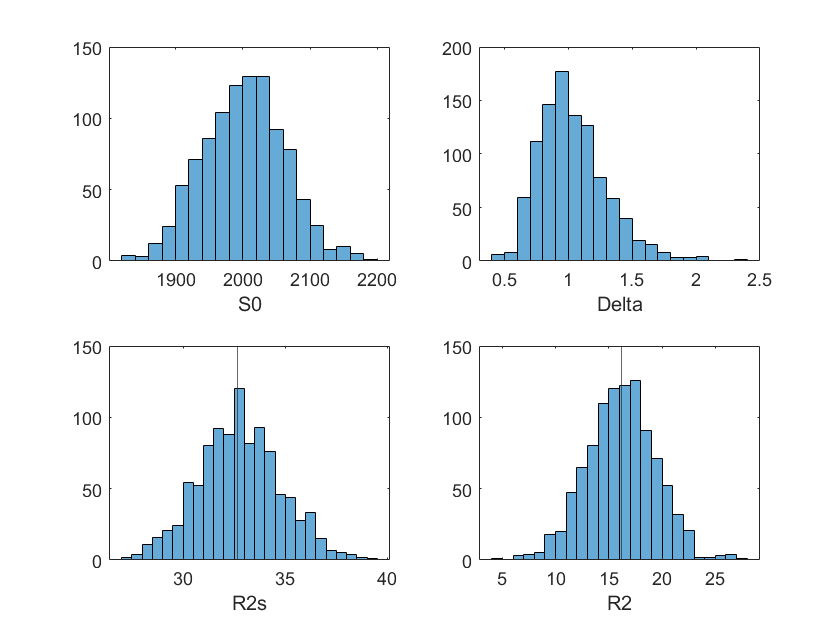


% Y = [1   0      -te1          0;
%      1   0      -te2          0; 
%      1  -1  -Spin_echo+te3  Spin_echo-2*te3;
%      1  -1  -Spin_echo+te4  Spin_echo-2*te4;
%      1  -1  -Spin_echo+te5  Spin_echo-2*te5;
%      1  -1         0        -Spin_echo];
Y = zeros(num_echos,4);
for ii = 1:num_echos
    if ii == 1
        Y(1,:) = [1   0      -te1          0];
    elseif ii == 2
        Y(2,:) = [1   0      -te2          0];
    elseif ii >2
        Y(ii,:) = [1  -1  -Spin_echo+echo_times(:,ii)  Spin_echo-2*echo_times(:,ii)];
    else
        Y(end,:) = [1  -1         0        -Spin_echo];
    end
    
end

% Multiplying the inverse of Y to each echo
noisyS = zeros(N,num_echos);
noisyS_NL = zeros(N,num_echos);
for i = 1:N
    noisy_sig = abs(pred + randn(size(pred)) ./ SNR .* (S01 )  );
    noisyS(i,:) = log(noisy_sig);
    noisyS_NL(i,:) = noisy_sig;
end

S=noisyS';A = Y \ S;vec_S0 = A(1,:);vec_delta = A(2,:);vec_R2s = A(3,:);vec_R2 = A(4,:);
figure(2)
title('Linear Algebra Fitting')
subplot(2,2,1);histogram(exp(vec_S0));xlabel('S0');
subplot(2,2,2);histogram(exp(vec_delta));xlabel('Delta');subplot(2,2,3);histogram(vec_R2s);xline(R2s );xlabel('R2s')
subplot(2,2,4);histogram(vec_R2 );xline(R2);xlabel('R2')

predS = zeros(num_echos,N);
residuals = zeros(num_echos,N);
for i = 1:N
    predS(:,i) = SAGE_biexp4p([exp(vec_S0(i)) exp(vec_delta(i)) vec_R2s(i) vec_R2(i)],echo_times);
    residuals(:,i) = predS(:,i)-pred';
end
disp(min(vec_R2))

    4.8873



figure;

Using nonlinear fittng. Fit the data according to the piecwiese formula in:

Schmiedeskamp H, Straka M, Bammer R. Compensation of slice profile mismatch in combined spin- and gradient-echo echo-planar imaging pulse sequences. Magn Reson Med. 2012 Feb;67(2):378–88. 

As such:


$$S_0(\tau) = \[ \begin{cases} 
      S_0^I exp(-\tau R_2^*) & \tau <{TE}{2} \\
      \frac{S_0^I}{S_0^{II}} exp(-TE(R_2^*-R_2)) exp(-\tau(2R_2-R_2^*)) & \frac{TE}{2}< \tau < TE \\
   \end{cases}
\]
$$


ub = [Inf Inf Inf Inf];
lb = [0 0 0 0];
p0=[2000 1 75 20]; % bad guesses
fitY=zeros(N,4);
% Non-linear Fitting
tic
for i = 1:N
    fitY(i,:) = fitSAGE(echo_times,noisyS_NL(i,:),p0,'n');
end
toc

Elapsed time is 6.873611 seconds.


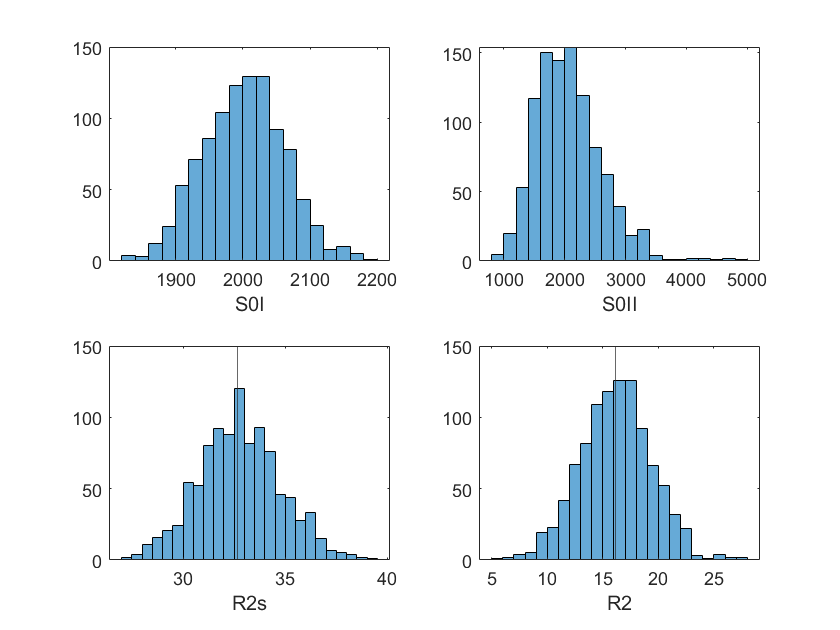

figure(1)
title('Non-linear Fit')
subplot(2,2,1)
histogram(fitY(:,1))
xlabel('S0I')
subplot(2,2,2)
histogram(fitY(:,2))
xlabel('S0II')
subplot(2,2,3)
histogram(fitY(:,3))
xline(R2s )
xlabel('R2s')
subplot(2,2,4)
histogram(fitY(:,4))
xline(R2 )
xlabel('R2')

## Overlay

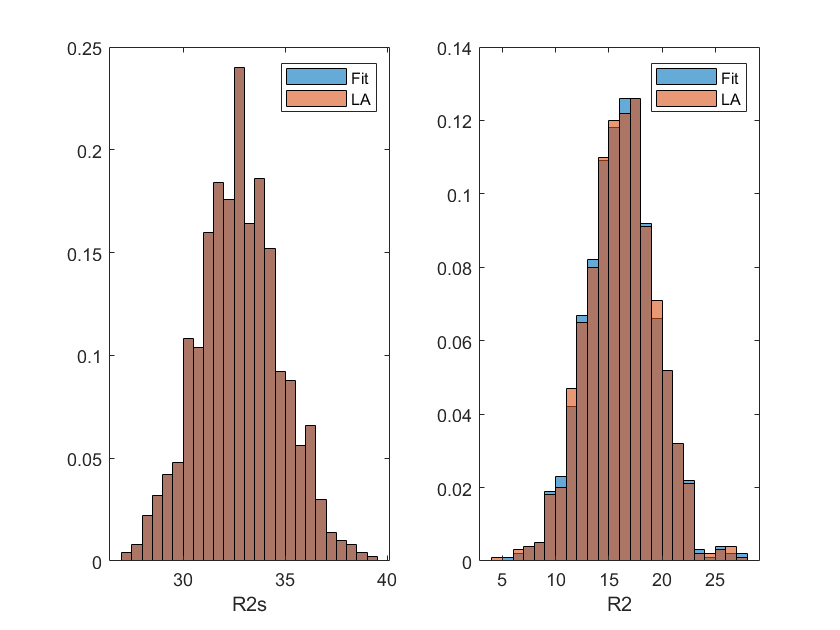

figure;
subplot(1,2,1)
histogram(fitY(:,3),'Normalization','pdf');hold on;histogram(vec_R2s,'Normalization','pdf');legend Fit LA
xlabel('R2s')
subplot(1,2,2)
histogram(fitY(:,4),'Normalization','pdf');hold on;histogram(vec_R2,'Normalization','pdf');legend Fit LA
xlabel('R2')